clear,clc, close all;
addpath(pathdef)

import casadi.*

% Params
T = 0.1;          % sampling time
N = 15;           % prediction horizon
sim_time = 15;    % maximum simulation time (sec)

% states limit
x_max = 0.43; % m
x_min = -x_max;
xd_max = 2.0; % m/s
xd_min = -xd_max;
q_max = inf;  % rad
q_min = -q_max;
qd_max = inf; % rad/s
qd_min = -qd_max;
u_max = 3 * 9.81;
u_min = -u_max;

% cost function penalties
Q = diag([3, 0, 3, 0]);   % states penalty
R = 0.1;     % controls penalty

% initial condition [x; x_d; q; q_d]
x0 = [0; 0; 180/180*pi; 0];   % initial pose

% target condition
xs = [0; 0; 0; 0];   % reference pose

% states
x = SX.sym('x');
x_d = SX.sym('x_d');
q = SX.sym('q');
q_d = SX.sym('q_d');
states = [x; x_d; q; q_d];
n_states = length(states);

% controls
u = SX.sym('u');
controls = u;
n_controls = length(controls);

% continuous state space sys
X_dot = continuous_cartpend(states, u);
f_continuous = Function('f_continuous', {states, controls}, {X_dot}, ...
    {'states', 'controls'}, {'X_dot'}); % function to compute state derivative

## Optimization problem setup

% Optimization variables and params
opti = Opti();
x = opti.variable(n_states, N + 1); % decision variables (states)
u = opti.variable(n_controls, N);   % optimization variables (controls)
p0 = opti.parameter(n_states, 1);   % initial states
p1 = opti.parameter(n_states, 1);   % final states

% define cost function
diffStates = x - p1;
objFunc = trace(diffStates'*Q*diffStates) + trace(u'*R*u);
opti.minimize(objFunc);

% define constraints
opti.subject_to( x(:, 1)==p0 );  % init state
for k = 1:N
    opti.subject_to(x(:, k+1) == RK4(x(:, k), u(:, k), f_continuous, T)) % dynamics constraints
end

opti.subject_to(abs(x(1, :)) <= x_max);
opti.subject_to(abs(x(2, :)) <= xd_max);
opti.subject_to(abs(x(3, :)) <= q_max);
opti.subject_to(abs(x(4, :)) <= qd_max);

opti.subject_to(abs(u(1,:)) <= u_max);

opti

opti = Opti {
  instance #30
  #variables: 2 (nx = 79)
  #parameters: 2 (np = 8)
  #constraints: 21 (ng = 143)
  CasADi solver needs updating.
}

% solver
% define solver options
opts.ipopt.max_iter = 100;
opts.ipopt.print_level = 0; % 0 -> 3
opts.ipopt.acceptable_tol = 1e-8;
opts.ipopt.acceptable_obj_change_tol = 1e-6;

% define plugin options
opts.print_time = 0; % 0, 1

opti.solver('ipopt', opts);

% set initial condition
opti.set_value(p0, x0);
opti.set_value(p1, xs);
% sol = opti.solve()

% cartPend solver
OCP = opti.to_function('OCP', {p0, p1}, {x, u}, ...
    {'init_states', 'target_states'}, {'traj_opt', 'ctrl_opt'})

OCP = OCP:(init_states[4],target_states[4])->(traj_opt[4x16],ctrl_opt[1x15]) MXFunction

[x_opt, u_opt] = OCP(x0, xs)

x_opt = [[-3.66042e-12, 0.1, 0.3, 0.43, 0.43, 0.43, 0.429939, 0.429914, 0.43, 0.395681, 0.371366, 0.365331, 0.395356, 0.422303, 0.420965, 0.372669], 
 [-1.72491e-12, 2, 2, 0.6, -0.6, 0.6, -0.601226, 0.600734, -0.599016, -0.0873614, -0.398934, 0.278223, 0.322289, 0.216634, -0.243392, -0.722514], 
 [0.657253, 0.392136, -0.120865, -0.339494, -0.089551, 0.104133, 0.351997, 0.799347, 1.5434, 2.91388, 4.39866, 5.35387, 5.79473, 6.00493, 6.2163, 6.6341], 
 [-3.74039e-13, -5.67524, -5.01757, 0.352075, 4.88739, -0.813715, 5.90172, 3.65325, 10.8294, 16.4387, 12.3624, 6.31333, 2.85769, 1.53285, 2.88131, 5.79071]]

u_opt = [[20, -4.19455e-10, -14, -12, 12, -12.0123, 12.0196, -11.9975, 5.11655, -3.11573, 6.77157, 0.440659, -1.05655, -4.60026, -4.79122]]


% TODO: improve this by initial guess of u0
% Simulation loop
% ------------------------------------------------------------------------------------
% ------------------------------------------------------------------------------------
% ------------------------------------------------------------------------------------
t0 = 0;

xx(:, 1) = x0;                 % keep history of states during the whole simulation
u0 = zeros(N, n_controls);     % two control inputs
X0 = repmat(x0, 1, N+1);       % init states variables along first prediction window
t(1) = t0;                     % keep history of time

% start MPC
mpcIter = 0;
xx1 = []; % to store predicted states
u_cl = []; % to store predicted controls we take (the first one in the all optimal controls)

main_loop = tic;
while((norm((x0 - xs), 2) > 1e-6) && ((mpcIter * T) < sim_time)) % terminate when the robot is within 1 cm of the destination or sim time is over
    
    % solution consists of both optimal control (u_opt) and optimal trajectory (X_opt)
    [x_opt, u_opt] = OCP(x0, xs);

    % get only opt control from the solution
    u_opt = full(u_opt)';

    % get only opt traj from the solution
    xx1(:, 1:n_states, mpcIter + 1) = full(x_opt)';

    u_cl = [u_cl; u_opt(1, :)]; % store only the first control

    t(mpcIter + 1) = t0;

    % [t0, x0, u0] = shift(T, t0, x0, u + randn()/10, f_continuous); % apply only the first control
    [t0, x0, u0] = shift(T, t0, x0, u_opt, f_continuous); % apply only the first control
    
    xx(:, mpcIter + 2) = x0;

    mpcIter = mpcIter + 1;
end
main_loop_time = toc(main_loop);
disp(main_loop_time/mpcIter);

    0.0335



% ------------------------------------------------------------------------------------
% ------------------------------------------------------------------------------------
% ------------------------------------------------------------------------------------

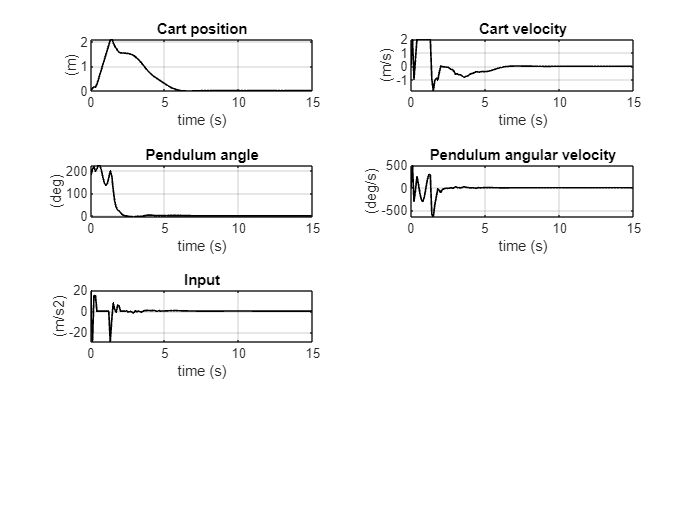

tiledlayout(4, 2, "TileIndexing","rowmajor");
nexttile;
plot(t, xx(1,1:end-1), "LineWidth", 1, "Color", [0 0 0]);
title('Cart position');
xlabel("time (s)");
ylabel("(m)");
grid on;

nexttile;
plot(t, xx(2,1:end-1), "LineWidth", 1, "Color", [0 0 0]);
title('Cart velocity');
xlabel("time (s)");
ylabel("(m/s)");
grid on;

nexttile;
plot(t, rad2deg(xx(3,1:end-1)), "LineWidth", 1, "Color", [0 0 0]);
title('Pendulum angle');
xlabel("time (s)");
ylabel("(deg)");
grid on;

nexttile;
plot(t, rad2deg(xx(4,1:end-1)), "LineWidth", 1, "Color", [0 0 0]);
title('Pendulum angular velocity');
xlabel("time (s)");
ylabel("(deg/s)");
grid on;

nexttile;
plot(t, u_cl, "LineWidth", 1, "Color", [0 0 0]);
title('Input');
xlabel("time (s)");
ylabel("(m/s2)");
grid on;